Matlab project 1

%1. Read data into Matlab
clear; clc;
data1 = xlsread("LaneChange_120.xlsx"); %% 많이 안쓴다함
data = readtable("LaneChange_120.xlsx"); 
data_arr= data{:,:}    % 테이블에서 {} 사용하여 value 배열 뽑기

%2. Find NaN and replace a number calculated by linear interpolatrion
% Nanarr = isnan(data_arr)
% idx = find(Nanarr)
% data_arr(idx)
% data_arr(idx) = (data_arr(idx+1)+data_arr(idx+2))/2
% data_arr(idx)
data{:,:} = fillmissing(data{:,:},"linear") %테이블 형식 유지

data = 2857×21 table
    Car_tx      Car_ty       Car_tz       Car_vx         Car_vy        Car_vz      Time     Vhcl_Distance    Vhcl_FL_ty     Vhcl_FL_tz    Vhcl_FR_ty    Vhcl_FR_tz    Vhcl_Fr1_x    Vhcl_Fr1_y     Vhcl_RL_ty    Vhcl_RL_tz    Vhcl_RR_ty    Vhcl_RR_tz    Vhcl_Steer_Ang     Vhcl_Yaw        Vhcl_v  
    ______    ___________    _______    ___________    ___________    _________    _____    _____________    ___________    __________    __________    __________    __________    ___________    __________    __________    __________    __________    ______________    ___________    __________

    22.194    -1.2007e-06    0.60288              0              0            0        0              0      -0.00012803      0.01521     0.00012792     0.015214           20        7.262e-10    0.0020166       0.01881     -0.0020074     0.018812                0      -6.2734e-10             0
    22.194    -1.2008e-06    0.60288    -0.00088559    -4.0672e-08    0.0001129    0.001     

%3.
z = (19.021<=data.Time&data.Time<=24.551)

z = 2857×1 logical 배열
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


Time = data.Time(z)

Time =    19.0210
   19.0310
   19.0410
   19.0510
   19.0610
   19.0710
   19.0810
   19.0910
   19.1010
   19.1110


length(Time)

ans = 553

%4
dearr = rad2deg(data.Vhcl_Steer_Ang)

dearr =          0
         0
   -0.0044
   -0.0101
    0.0065
    0.0478
    0.1044
    0.1665
    0.2282
    0.2872


v = data.Car_ty(z)

v =    -0.2280
   -0.2283
   -0.2286
   -0.2289
   -0.2292
   -0.2294
   -0.2297
   -0.2300
   -0.2303
   -0.2305


dearr = dearr(z)

dearr =     0.5038
    0.5266
    0.5513
    0.5738
    0.5940
    0.6170
    0.6489
    0.6925
    0.7442
    0.7954


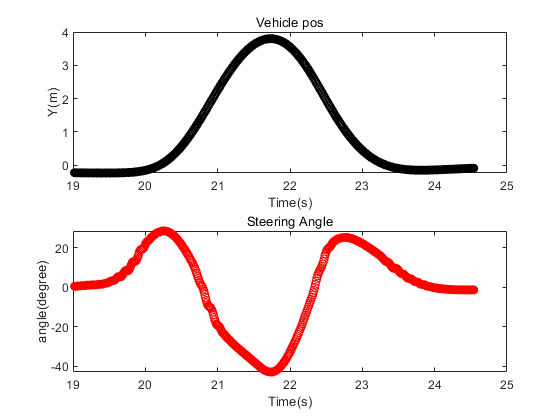

figure("Name","test")
subplot(2,1,1)
plot(Time,v,"blacko")
title("Vehicle pos")
xlabel("Time(s)")
ylabel("Y(m)")
%xlim([Time(0),Time(end)])
%ylim([min(v),max(v)])
subplot(2,1,2)
plot(Time,dearr,"ro")
title("Steering Angle")
xlabel("Time(s)")
ylabel("angle(degree)")

%5 
ss = 430<=data.Car_tx &data.Car_tx<=620

ss = 2857×1 logical 배열
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


Ltime = data.Time(ss)

Ltime =    17.8610
   17.8710
   17.8810
   17.8910
   17.9010
   17.9110
   17.9210
   17.9310
   17.9410
   17.9510


Laptime = Ltime(end)-Ltime(1)

Laptime = 5.7300